%Launch the MyoUdp.exe interface application from the +Inputs directory of the MiniVIE package 


## Set up the MiniVIE path

cd('C:\Users\student\Documents\GitHub\HRI-LABS-BBALL\HRI\Drivers\MiniVIE');
MiniVIE.configurePath;

[MiniVIE.m] Configured MiniVIE path at: C:\Users\student\Documents\GitHub\HRI-LABS-BBALL\HRI\Drivers\MiniVIE



%% Create an object for UDP interface to the Myo Armband
hMyo = Inputs.MyoUdp.getInstance();

[MyoUdp] Returning existing object


hMyo.initialize();

[UserConfig.m] myoUdpRate=200
[MyoUdp] UDP Comms already initialized


cd('C:\Users\student\Documents\GitHub\HRI-LABS-BBALL\HRI\Lab2_EMGInterfacing');



## Plot some EMG Activity

Get some data and plot.  Note: You may have to run getData again if the first graph presents a flat line at zero due to the initialization sequence.

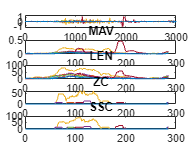

%% Get data and plot.  emgData size is [1000 samples x 8 channels]

%emgData = hMyo.getData;

channels = 8;
time_s = 3; %This variable time is in seconds
SAMPLE_RATE = 1000; %200 = hertz
num_sample = time_s * SAMPLE_RATE;


hMyo.getData(num_sample, 1:channels);

emg = hMyo.getData(num_sample, 1:channels);

%pause(4)

plot(emgDataRight)
xlabel('Sample Number');
ylabel('EMG Signal')

%hViewer = GUIs.guiSignalViewer(hMyo);


%% Extract features from data
%%%%%%%%%%%%%%%%%%%%%%

% setup constants for feature extraction
featureNames = {'MAV' 'LEN' 'ZC' 'SSC'};
num_channels = 8; % 8 channels in myo band
num_features = length(featureNames);
num_emg_samples = size(emg,1);

windowSize = 150; % number of samples to compute features
binSize = 10; % number of sample to advance across samples
zc_thresh = 0.1;  % threshold vaue for zero crossing
ssc_thresh = 0.1; % threshold vaue for slope sign changes
Fs = 1000; % sample rate

% create indices for start and end of sliding data windows
idxStart = 1:binSize:num_emg_samples-windowSize-1;
idxEnd = idxStart+windowSize-1;
num_feature_samples = length(idxStart);

% preallocate feature matrix
features = zeros(num_channels, num_features, num_feature_samples);

% loop through and slide window by increment and perform feature extraction
for b = 1:length(idxStart)
    windowData = emg(idxStart(b):idxEnd(b),:);
    f = feature_extract(windowData',windowSize,zc_thresh,ssc_thresh,Fs);
    features(:,:,b) = f;
end

figure(4)
% Plot results of feature extract:
num_plots = 1 + length(featureNames);
subplot(num_plots,1,1)
plot(emg)
ylim([-1.5 1.5])
%title(filename,'Interpreter','None')
for i = 2:num_plots
    subplot(num_plots,1,i)
    iFeature = i-1;
    plot(squeeze(features(:,iFeature,:))')
    title(featureNames{iFeature})
end



save('myEMGData_Shot_20.mat','emg')

save('FeatureData\myEMGData_Shot_20_F.mat','features')
